# PhysioNet Challenge 2016: Classify normal and abnormal heart sounds

This script demonstrates the complete workflow for developing an embedded machine learning application,including acquiring the data, extracting features, exploring various algorithms, tuning to get a model with good performance, and  deploying the model in a prototype application. Specifically, we develop a classifier of heart sounds into 'Normal' and 'Abnormal', which could be used in the medical practice to monitor patients who are at increased risk of dangerous heart conditions, and remove the need to have a skilled clincian present. 

The figure below shows the high-level architecture and a screenshot from the prototype.

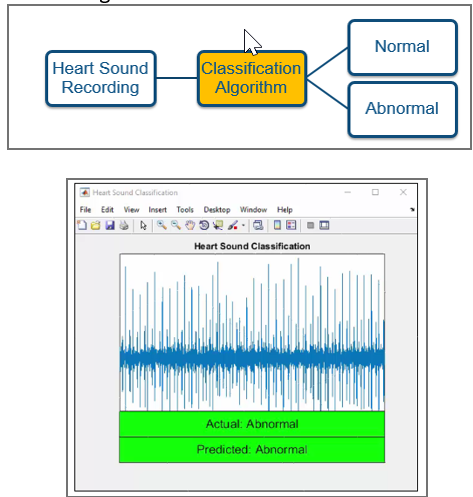

For this application, we use the dataset provided by the [PhysioNet challenge of 2016](https://archive.physionet.org/pn3/challenge/2016/), consisting of over 3000 recordings of normal and abnormal hearts. These recordings were obtained at four different locations - aortic, pulmonic, trcuspid and mitral areas - using phonocardiograms.

To get us started, we need to obtain the data. If you are running this for the first time, this step will download data from PhysioNet's website. This step will be skipped if the "Data" directory is present. Or if you don't intend to actually run feature extraction or train the models (both of which can take several minutes to execute), you don't have to worry about actually getting the training and validation dataset. Instead, just extract the demonstration zipfile (that's included) and you can simply load the precomputed features from the .mat file, and then train models in the Classification Learner App.

***Note***: This may take a while depending on your internet speed.

% definitely make sure we've got the validation data set
if ~exist('validation.zip')%#ok 
   % you need the validation data only for running the prototype app
   try
       validation_url = 'https://archive.physionet.org/pn3/challenge/2016/validation.zip';
       websave('validation.zip', validation_url);
   catch
       warning("Failed to access heart sound validation data on physionet.org - check whether path %s needs updating", validation_url)
   end
   
   unzip('validation.zip', 'Data');
end

% by default, skip downloading training data (may take long time, 185 MB)
% (though you won't be able to execute the feature extraction yourself below)
getTrainingData = false;   
if ~exist('training.zip') && getTrainingData%#ok 
    % fetch training data from physionet site. 
    % NOTE: unless you plan to execute the feature extraction, don't worry if there is an error here,
    %       we only need access to the training set to run the feature extraction 
    try
        training_url = 'https://archive.physionet.org/pn3/challenge/2016/training.zip';
        websave('training.zip', training_url);
    catch
        warning("Failed to access heart sound training data on physionet.org - check your internet connection or whether path %s needs updating",training_url)
    end
    
    unzip('training.zip', 'Data/training')
end

% make sure we have copies of the two example files in the main directory
if exist('Data/validation')%#ok
    copyfile 'Data/validation/a0002.wav';
    copyfile 'Data/validation/a0011.wav';
end

Add current folder and subfolders to search path, so the script can find the recordings in subdirectories of "Data", and various MATLAB functions in "HelperFunctions".

addpath(genpath(pwd));
addpath('./HelperFunctions');
warning off;                      % suprress warning messages

The remainder of this demo is structured according to the four phases of the typical machine learning workflow:

- Access and Explore Data

- Preproess Data

- Develop Predictive Models

- Integrate Models with Systems

The figure below shows which additional MATLAB toolboxes we will leverage in the various phases of the workflow.

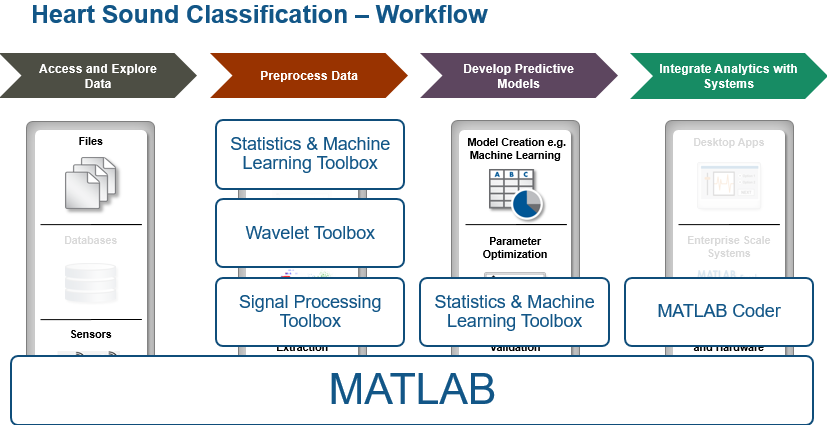

## 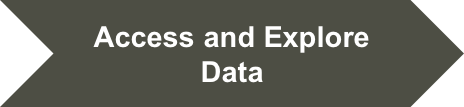

## What does an abnormal heart sound like?

Let's begin by forming an impression what these heart signals sound like. MATLAB provides functions to play back audio. For this exercise, we copied samples of normal and abnormal heart recordings from the dataset into the main directory.

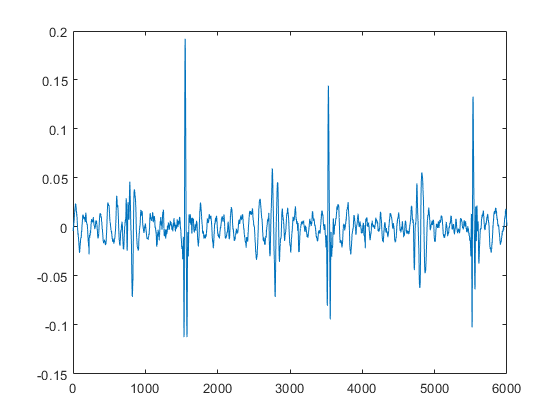

[PCG_abnormal, fs] = audioread('a0001.wav');
p_abnormal = audioplayer(PCG_abnormal, fs);
play(p_abnormal, [1 (get(p_abnormal, 'SampleRate') * 3)]);

% Plot the sound waveform
plot(PCG_abnormal(1:fs*3))

## What does a normal heart sound like?

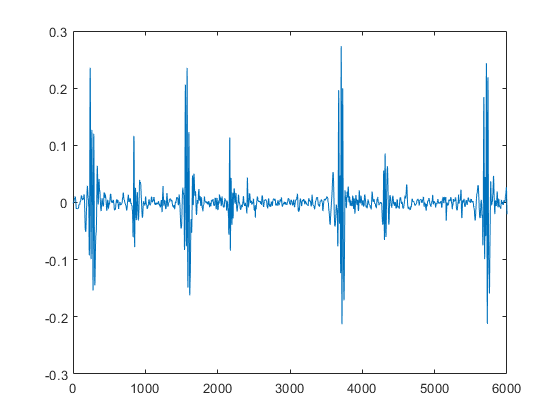

[PCG_normal, fs] = audioread('a0011.wav');
p_normal = audioplayer(PCG_normal, fs);
play(p_normal, [1 (get(p_normal, 'SampleRate') * 3)]);

% Plot the sound waveform
plot(PCG_normal(1:fs*3))

## 

## What do the signals look like in the frequency domain?

To explore what we might use to distinguish these signals with a classifier, let's look at their frequency content. To this end, you can use MATLAB's [Signal Analyzer](https://www.mathworks.com/help/signal/ug/getting-started-with-signal-analyzer-app.html) app to inspect and compare the power spectrum of the two signals.

signalAnalyzer(PCG_normal, PCG_abnormal)

Once the app has loaded, display the signals in two separate panels (use the Grid button on the left upper corner), and then generate the Spectrum underneath the waveform (by clicking the corresponding button). The abnormal sound will show a clear spike near 0.2 radians, whereas the normal sound has more frequency content right near the y-axis.

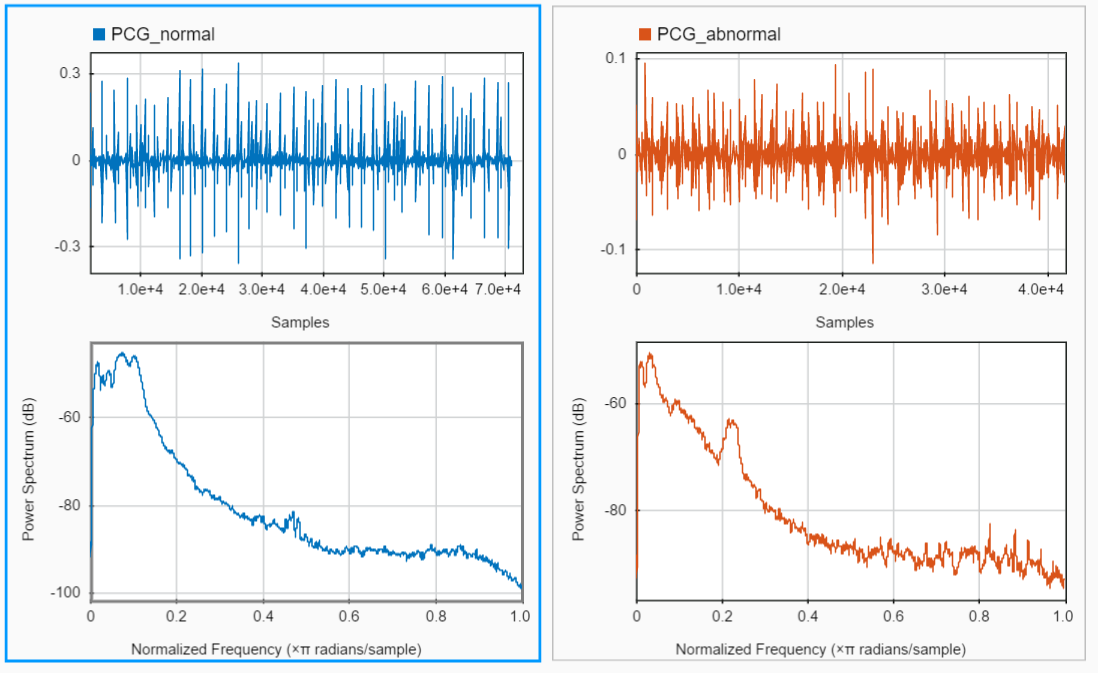

## 

## Prepare to read the data into memory

To load the recordings into memory, MATLAB's [fileDatastore](https://www.mathworks.com/help/matlab/ref/filedatastore.html) provides a convenient way to handle a large number of data files spread across multiple folders. The read function provides flexibility to access a wide variety of different file formats, and with MATLAB's base read functions typically little customization is needed. 

% expecting the training data in subfolders of 'Data\training\*': "training-a", etc
training_fds = fileDatastore(fullfile(pwd, 'Data', 'training'), 'ReadFcn', @importAudioFile, 'FileExtensions', '.wav','IncludeSubfolders',true);

다음 사용 중 오류가 발생함: fileDatastore (226번 라인)
'C:\Users\User\Desktop\HeartSoundClassificationNew-FX-Oct19\HeartSoundClassificationNew-FX\Data\training'과(와) 일치하는 파일이나 폴더를 찾을 수 없습니다.

## 

## Create a table with filenames and labels

"Labels" (or also "ground truth") represent the true category of each sample in a dataset and are critical to be able to apply  "supervised" machine learning to this classification task. The dataset we are using here provides the labels in a separate REFERENCE file in each subfolder of the training and validation data, along with the corresponding audio files (recordings). So in this section we read these REFERENCE.csv files and build a table with filename and corresponding label. This step is only needed if you want to run feature extraction in the next step.

data_dir = fullfile(pwd, 'Data', 'training');
folder_list = dir([data_dir filesep 'training*']);

reference_table = table();

for ifolder = 1:length(folder_list)
    disp(['Processing files from folder: ' folder_list(ifolder).name])
    current_folder = [data_dir filesep folder_list(ifolder).name];
    
    % Import ground truth labels (1, -1) from reference. 1 = Normal, -1 = Abnormal
    reference_table = [reference_table; importReferencefile([current_folder filesep 'REFERENCE.csv'])];
end

## 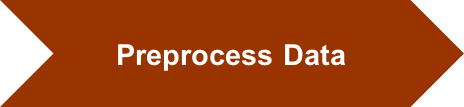

## Extract features from raw heart sound signals

Next we need to extract features from the raw recordings. We use statistical and signal processing functions available in MATLAB to process and extract features from the raw heart sound signal. The following section extracts some 26 features for each recording, and splits each recording into windows consisting of 5 seconds of heart sound.

The preprocessing of all 3000+ recordings may take a while, even though the code below leverages the Parallel Computing toolbox to execute on multiple cores (provided your machine is multicore). To avoid waiting, by default the code will simply load the extracted features from the FeatureTable that we included with the demo.

runExtraction = false; % control whether to run feature extraction (will take several minutes)
   % Note: be sure to have the training data downloaded before executing
   % this section!
if runExtraction | ~exist('FeatureTable.mat')%#ok 
    % Window length for feature extraction in seconds
    win_len = 5;
    
    % Specify the overlap between adjacent windows for feature extraction in percentage
    win_overlap = 0;
    
    % Initialize feature table to accumulate observations
    feature_table = table();
    
    % Use Parallel Computing Toobox to speed up feature extraction by distributing computation across available processors
    
    % Create partitions of the fileDatastore object based on the number of processors
    n_parts = numpartitions(training_fds, gcp);
    
    % Note: You could distribute computation across available processors by using 
    % parfor instead of "for" below, but you'll need to omit keeping track
    % of signal lengths
    parfor ipart = 1:n_parts
        % Get partition ipart of the datastore.
        subds = partition(training_fds, n_parts, ipart);
        
        % Extract features for the sub datastore
        [feature_win,sampleN] = extractFeatures(subds, win_len, win_overlap, reference_table);
        
        % and append that to the overall feature table we're building up
        feature_table = [feature_table; feature_win];
        
        % Display progress
        disp(['Part ' num2str(ipart) ' done.'])
    end
    save('FeatureTable', 'feature_table');

else % simply load the precomputed features
    load('FeatureTable.mat');
end

% Take a look at the feature table
disp(feature_table(1:5,:))

## 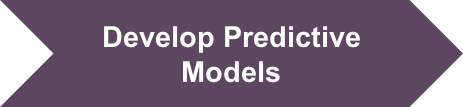

## Train, compare and select classifier 

Having an initial set of features, we can proceed to the next phase of the machine learning workflow, the training of various predictive models. You can use the [Classification Learner App](https://www.mathworks.com/help/stats/classificationlearner-app.html) to interactively train, compare and select classifiers.

classificationLearner

Select the "feature_table" variable from the workspace as your data, and either hold out 30% as model "validation" data (to match the results from the eBook and programmatic workflow below), or (to preserve more data for training) choose cross validation. 

Then train a bunch of different classifiers, including linear regression, SVM, and decision trees. Note which ones deliver higher accuracy on the held out validation data. Also explore the confusion matrices and conceptualize what misclassifying a normal versus an abnormal sound means in practice. You should see results similar to this (but not identical, because there's various random processed involved in selecting data and starting points of algorithms):

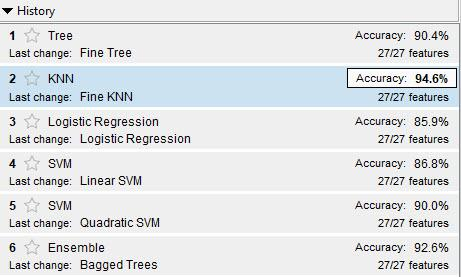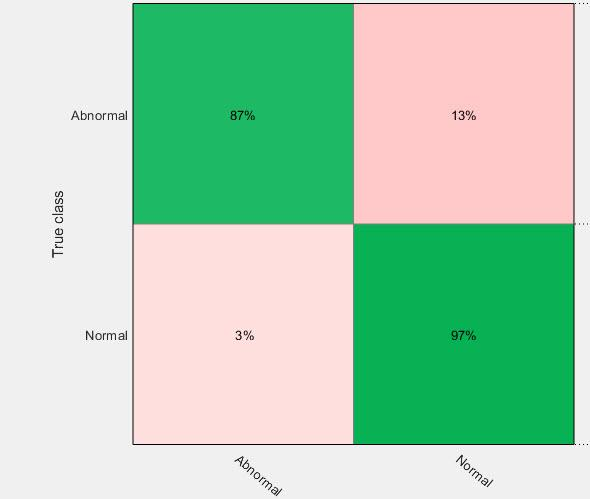

If you look at the Confusion Matrix (click button next to "Train"), you'll noticfe a fairly  number of abnormal sounds are misclassified as normal (13% for the  "Fine KNN" model shown above on the right), which is very undesirable in medical practice because it means failing to diagnose someone who might have a serious heart condition. To improve model performance, the following sections will apply additional optimization steps.

## 

## Optimize an initial model

Development of machine learning models is inherently an iterative process, to achieve optimal performance you will generally need to apply advanced techniques and iterate. 

First, the saying goes "there is no free lunch", which in machine learning means for any given machine learning problem even experts don't know which type of model will perform best. You have to do some work to achieve optimal performance. So first step is to try out different models. The Classification Learner makes that easy. If you haven't already, go back to the Classification Learner, try a bunch of different models, and compare their performance. Which one performed best?

Other common approaches to improve model performance include:

- Tuning model parameters. Those are often called "hyperparameters" to distinguish them from the parameters that are learned during normal model training. We will apply this technique in the next section.

- Transforming existing or extracting new features. If the current feature set doesn't capture all the variation inherent in the data, using different features is likely to help. Finding the optimal feature set remains one of the aspects of machine learning that require significant expertise. MATLAB provides additional tools to facilitate that process, including for signals like heart sounds.

- Improving preprocessing and/or adding more training data

- Addressing imbalances in the data. - For the heart sound data, we have relatively few abnormal heart sounds but very many normal ones. Introducing a bias (with misclassification cost) helps overcome such imbalances. We'll try that in the next section.

- Making other task-specific tradeoffs. Aside from reducing specific misclassifications with high negative impact at the cost of accepting lower overall accuracy, you may make other tradeoffs in optimizing your model. For example, for deployment you may have to reduce the size of the model so it fits on the limited memory of an embedded device. Further below we demonstrate a technique for selecting a subset relevant features to train a much smaller model while maintaining overall accuracy.

### Optimize model by tuning hyperparameters

As mentioned above, a powerful tool for improving model accuracy is hyperparameter optimization. With R2019b, this process is available directly in the Classification Learner. Simply select one of the "Optimizable" models from the model gallery (as shown below), adjust the Advanced "Optimizer Options" appropriately, and click "Train" like before. To limit run time to a few minutes, set a time limit to an explicit value, or limit the #iterations (15 iterations are plenty for this data set). - If you are on an earlier release, skip ahead to the section on programmatic model training. 

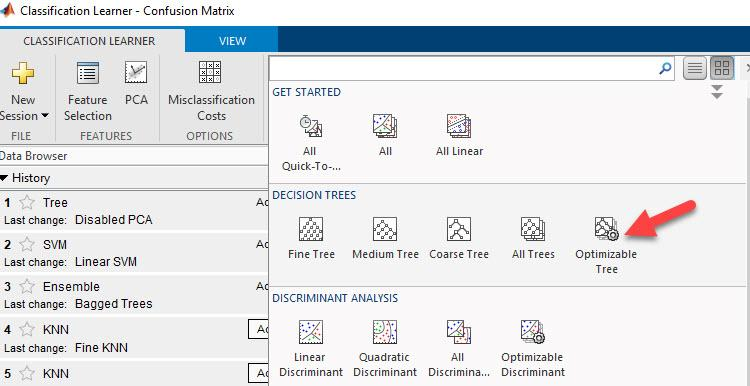

**TO DO**: tune the hyperparameters of at least one of the models you trained above. [Click here](matlab:web(fullfile(docroot, 'stats/hyperparameter-optimization-in-classification-learner-app.html'))) to view more details on the advanced options and limitations of hyperparameter tuning in our documentation. For more information on Bayesian optimization in general, [click here](matlab:web(fullfile(docroot, 'stats/bayesian-optimization-workflow.html'))).

The display will show a progress plot of the classification error, along with current hyperparameter settings. 

*Note: Depending on the particular random numbers that are generated, the best hyperparameters could vary slightly. *

### Optimize the model using misclassification cost

We can use [grpstats](https://www.mathworks.com/help/stats/grpstats.html) to tally number of observations for each class and thus demonstrate the imbalance in our heart sound data. Like above, proceed with this section only if you have R2019b, otherwise skip to the programmatic equivalent presented in the next section.

% tabulate classes in training data
grpstats_all = grpstats(feature_table, 'class', 'mean');
disp(grpstats_all(:,'GroupCount'))

Moreover, in this application, failing to detect an actual heart condition (a so-called false negative) is much more serious than erroneously classifying a normal heart sound as abnormal.

We can remedy imbalances in our training data and reduce specific, impactful misclassifications by introducing a misclassification cost - at the expense of potentially lowering overall accuracy.

**TO DO:**

- Look at the confusion matrix of your currently best model (Click on "Confusion Matrix" to the right of the "Train" button). How many false negatives do you have?

- Penalize that misclassification with a cost of 10 or 20: Open the "Misclassification Costs" dialog, and set the value of the upper right corner.

- Retrain the model

- Did overall accuracy decrease - how much? Revisit the confusion matrix - how much were false negatives reduced (abnormal heart sound misclassified as normal)?

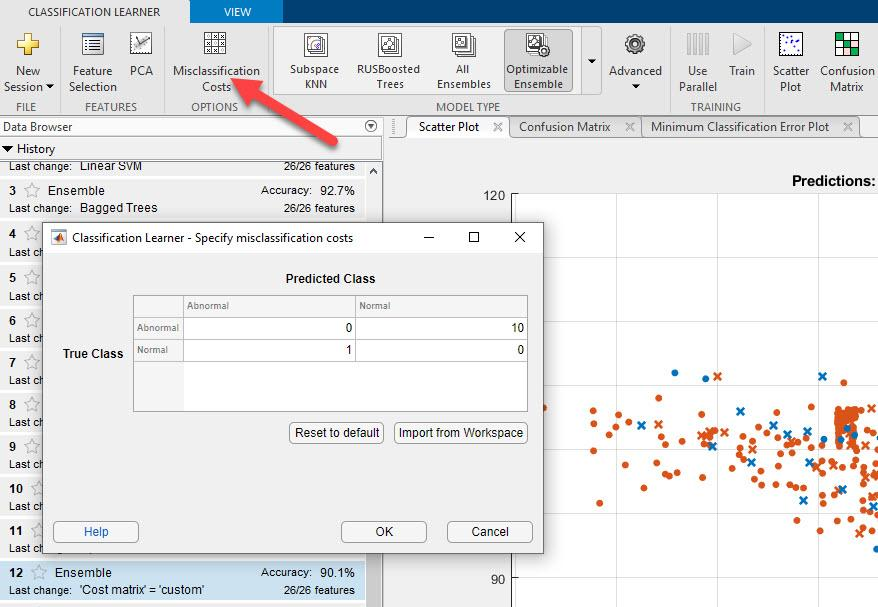

*Example results: The ensemble of trees ("random forest") performs at 93% initially, reduces false negatives from 15% down to 3% using a misclassification cost of 20 (and lowering overall accuracy to 87%). With that cost, the fine KNN reduces false negatives to below 1%, but also significantly looses overall accuracy from 94% to 83%.*

You can also perform these tasks programmatically. If you are interested in learning that, continue below. Otherwise, skip ahead to the section "Perform feature selection using Neighborhood Component Analysis".

## 

## To train and optimize models programmatically, you perform the following steps:

- Explicitly split your data into a training and test set, which you set aside for assessing accuracy

- Train a model using the 'Cost' and 'OptimizeHyperparameters' parameters

- Evaluate accuracy of model on held-out test set

### Split data into training and testing sets. 

You can split the data any way you want. Depending on the size of the data and how much tuning you expect to perform, you can hold out anwhere between 20% and 50% of the data for testing. Assuming you started up the Classification Learner holding out 30% of the data for testing, let's split the data the same way to match our work in the app. You can use [cvpartition](https://www.mathworks.com/help/stats/cvpartition.html) to split data into training and testing sets. 

% using split function defined at end of script to divide feature table
% into training and test set, holding out 30%
[training_set, test_set] = splitDataSets(feature_table,0.3);


### Train the classifier (programmatically) with misclassification cost

Like we did interactively above, we compensate for fewer 'Abnormal' observations in the data, and  bias the classifier towards fewer misclassifications of abnormal sounds, using a cost matrix that assigns higher misclassification cost to the 'Abnormal' class. At the same time, we perform hyperparameter tuning by using [Bayesian Optimization](https://www.mathworks.com/help/stats/bayesian-optimization-workflow.html) to find optimal values for model parameters. 

Since the ensemble of trees outperformed the SVM classifier in the Classification Learner, we continue with the ensemble. 

% Assign higher cost for misclassification of abnormal heart sounds
C = [0, 10; 1, 0];        

% Create a random sub sample (to speed up training) of 1/4 of the training set
%subsample = randi([1 height(training_set)], round(height(training_set)/4), 1);
% OR train on the whole training set
subsample = 1:height(training_set);

rng(1);

% Create a 5-fold cross-validation set from training data
cvp = cvpartition(length(subsample),'KFold',5);

% Step 2: train the model with hyperparameter tuning (unless you simply
% load an existing pre-trained model)

% train ensemble of decision trees (random forest)
disp("Training Ensemble classifier...")
    
% bayesian optimization parameters (stop after 15 iterations)
opts = struct('Optimizer','bayesopt','ShowPlots',true,'CVPartition',cvp,...
            'AcquisitionFunctionName','expected-improvement-plus','MaxObjectiveEvaluations',15);    
trained_model = fitcensemble(training_set(subsample,:),'class','Cost',C,...
        'OptimizeHyperparameters',{'Method','NumLearningCycles','LearnRate'},...
        'HyperparameterOptimizationOptions',opts)

% Step 3: evaluate accuracy on held-out test set

% Predict class labels for the validation set using trained model
% NOTE: if training ensemble without optimization, need to use trained_model.Trained{idx} to predict
predicted_class = predict(trained_model, test_set);

conf_mat = confusionmat(test_set.class, predicted_class);

conf_mat_per = conf_mat*100./sum(conf_mat, 2);

% Visualize model performance in heatmap
labels = {'Abnormal', 'Normal'};
heatmap(labels, labels, conf_mat_per, 'Colormap', winter, 'ColorbarVisible','off');

## 

## Perform feature selection using Neighborhood Component Analysis

The last model performs pretty well, but it is too large for deployment on a small embedded device. Therefore, in this section we explore training a more compact model that uses only a subset of the 26 features, namely the features that have the majority of the predictive power. [Neighborhood Component Analysis](https://www.mathworks.com/help/stats/neighborhood-component-analysis.html) (NCA) is an automated approach for  selecting a small subset of features that carry information most relevant to the classification task while minimizing redudancy among selected features. 

runNCA = true;   % control whether to see NCA running or just load the selected features
    
if ~runNCA && exist('SelectedFeatures.mat')%#ok
    % Load saved array of selected feature indexes
    load('SelectedFeatures.mat')
else % Perform feature selection with neighborhood component analysis
    rng(1);
    
    % first, let's make sure we've split the data (in case we skipped the
    % programmatic model training sections above)
    if ~exist('training_set')
        [training_set, test_set] = splitDataSets(feature_table,0.3);
    end
    
    mdl = fscnca(table2array(training_set(:,1:27)), ...
        table2array(training_set(:,28)), 'Lambda', 0.005, 'Verbose', 0);
    
    % Select features with weight above 1
    selected_feature_indx = find(mdl.FeatureWeights > 0.1);

    % Plot feature weights
    stem(mdl.FeatureWeights,'bo');
    
    % save for future reference
    save('SelectedFeatures', 'selected_feature_indx');
end

% Display list of selected features
disp(feature_table.Properties.VariableNames(selected_feature_indx))

## 

## Train model with selected features

To actually get a more compact model for deployment, we retrain the model using only selected features. Note how the file size decreased from 6G to 4G - maybe still not small enough, we could explore other models instead.

trainReducedModel = false;    % control whether to re-train this model or load it from a previous run

if trainReducedModel | ~exist('TrainedEnsembleModel_FeatSel.mat')%#ok
    % configure key parameters: cross validation, cost, and hyperparameter
    % tuning
    rng(1)
    cvp = cvpartition(length(subsample),'KFold',5);
    C = [0, 10; 1, 0];            % Assign higher cost for misclassification of abnormal heart sounds
    opts = struct('Optimizer','bayesopt','ShowPlots',true,'CVPartition',cvp,...
            'AcquisitionFunctionName','expected-improvement-plus','MaxObjectiveEvaluations',10);    
    
    % now we are ready to train...
    trained_model_featsel = fitcensemble(training_set(subsample,selected_feature_indx),training_set.class(subsample),'Cost',C,...
        'OptimizeHyperparameters',{'Method','NumLearningCycles','LearnRate'}, 'HyperparameterOptimizationOptions',opts)
    % save the model for later reference
    save('TrainedWaveletModel_FeatSel', 'trained_model_featsel');
else
    load('TrainedEnsembleModel_FeatSel.mat')
end

% Predict class labels for the validation set using trained model
predicted_class_featsel = predict(trained_model_featsel, test_set(:,selected_feature_indx));

conf_mat_featsel = confusionmat(test_set.class, predicted_class_featsel);

conf_mat_per_featsel = conf_mat_featsel*100./sum(conf_mat_featsel, 2);

labels = {'Abnormal', 'Normal'};

% Visualize model performance
% probably custom AE version: heatmap(conf_mat_per_featsel, labels, labels, 1,'Colormap', 'red','ShowAllTicks',1,'UseLogColorMap',false,'Colorbar',true);
heatmap(labels,labels,conf_mat_per_featsel, 'Colormap', winter, 'ColorbarVisible','off');

## 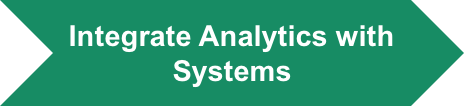

## Code Generation

Generate C code that takes recorded signal and sampling frequency as input and produces heart sound classification label as output. 

Instead of running codegen on the command line, if you were familiar with the Coder App and wanted to highlight this capability, you could bring up MATLAB Coder.

runCodegen = false;       % this typically takes several minutes
if runCodegen | ~exist('codegen/mex/classifyHeartSounds/classifyHeartSounds_mex')
    % Save trained model as a compact model for code generation
    saveLearnerForCoder(trained_model_featsel,'HeartSoundClassificationModel');
    
    % Alternatively, execute the following auto-generated MATLAB script to generate C code (and mex file, in current directory)
    classifyHeartSounds_codegen_script
    
    % saving the MEX file for future referene
    copyfile codegen/mex/classifyHeartSounds/classifyHeartSounds_mex.mexw64 HelperFunctions
end


## Validate final model

Process a random subset of audio files from the validation set by the sample app. The app calls the mex version of the function "classifyHeartSounds"

plotPredictions

In this demonstration, you've learned:

- How to efficiently acccess and preprocess a large set of signal data by leveraging MATLAB's data store and parfor functionality

- Quickly assess the performance of various "traditional" classification models using the interactive Classification Learner

- Optimize models, both interactively and programmatically

- Reduce model size by selecting a small subset of the most predictive features

- Automatically generate corresponding prediction code and integrate that into a simple demo application

To further improve performance and dive yet deeper into what's possible with signal classification, you could explore:

- Generating better features using techniques like Wavelet scattering. [This example ](https://www.mathworks.com/help/wavelet/examples/ecg-signal-classification-using-wavelet-time-scattering.html)demonstrates that for an ECG signal, and in the "Bonus" section below we guide you through that process for the heart sound signal.

- Applying Deep Learning, like in [this example](https://www.mathworks.com/help/signal/examples/signal-classification-with-wavelet-analysis-and-convolutional-neural-networks.html) for the same ECG data as referenced above.

Final note: A seminar walking through an earlier version of this demo is available in [this video](https://www.mathworks.com/videos/essential-tools-for-machine-learning-1481139920800.html )*.*

*I would like to acknowledge that this demo has been conceived and implemented by Kirthi Devleker. Contact him for more information about applying machine and deep learning to signals, working in the spectral domain, and applying techniques such as Wavelet scattering.*

*Copyright 2019 The MathWorks, Inc.*

## Bonus section: Automated Features Extraction using Wavelet Scattering

Since the Heart Sound demo was created in 2017 and the Machine Learning eBook was written, a lot of progress in automated extraction of features has been made. One technique particularly suitable for signals is wavelet scattering.

Wavelet scattering derives, with minimal configuration (i.e. almost automatic), low-variance features from signal (and image) data for use in machine learning and deep learning application, as shown in the figure below.

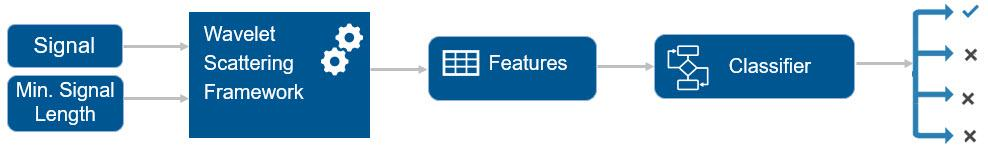

Wavelet transforms linearize small deformations such as dilations by separating the variations across different scales. For many natural signals, the wavelet transform also provides a sparse representation. While scattering can be compared to the filters implemented by the first layers of deep networks, an important distinctinon is that the wavelet filters are defined a priori as opposed to being learned. For more information about wavelet scattering, [click here](matlab:web(fullfile(docroot, 'wavelet/gs/wavelet-scattering.html'))).


% apply wavelet scattering to the whole training set (used also above)
N = 10000;         % min number of samples across whole data set (5 secs signal x 2,000 Hz)
sf = waveletScattering('SignalLength',N,'SamplingFrequency',2000);  % could try InvarianceScale 
[train_data,trainN] = extractWaveletFeatures(training_fds,sf, 10000,reference_table);


### Train a Classifier with Wavelet features

Above we generated 271 wavelet features automatically - all we had to do is manually is determine the minimum signal length. Training classifiers with these features works just like described above with the 27 manually "engineered" features.

With one quirk: since the wavelet transformation creates several observations from each signal, you cannot rely on random selection to "hold out" validation data, like provided conveniently in the Classification Learner. With random selection, you'd end up including some observations from the same signal in both training and validation data. Therefore, you have to manually "hold out" your test data for this exercise, and/or evaluate on a totally separate data set (like the validation data downloaded at the very beginning).

**TO DO:**

- Hold out a "test" set from train_data, for which you computed wavelet features above

- Using the Classification Learner, train a couple of models (skip "record_name" as predictor!)

- How much more accurate are they than your best result above?

- Apply feature selection to this model, and see how little accuracy you loose going back down to ~40 features

% This code will do #1, if you needed some help. You have a choice of
% holding out some data from the full training set, or process the
% validation data (which will be renamed test_set for compatibility with
% the accuracy measurement code further below)
if true
    % Hold out 0.3 as separate test set from the training data.
    % - Skipping column 1 which contains the record_name
    splitPt = round(height(train_data)*0.7);
    training_set = train_data(1:splitPt,2:273);
    test_set = train_data((splitPt+1):end,2:273);
    
    % Now train your model on "training_set" ...
else
    % Process the "official" validation set (provided by PhysioNet)
    
    % set up accessing validation data
    validation_dir = './Data/validation';
    reference_validation = importReferencefile([validation_dir '/REFERENCE.csv']);
    validation_fds = fileDatastore(validation_dir, 'ReadFcn', @importAudioFile, 'FileExtensions', '.wav');
    
    % compute wavelet features for validation data
    [validation_data,~] = extractWaveletFeatures(validation_fds,sf,N,reference_validation);
    
    % Use validation_data as your "test_set" below
    test_set = validation_data;
    test_set.record_name=[];      % ignore the record_name field
end

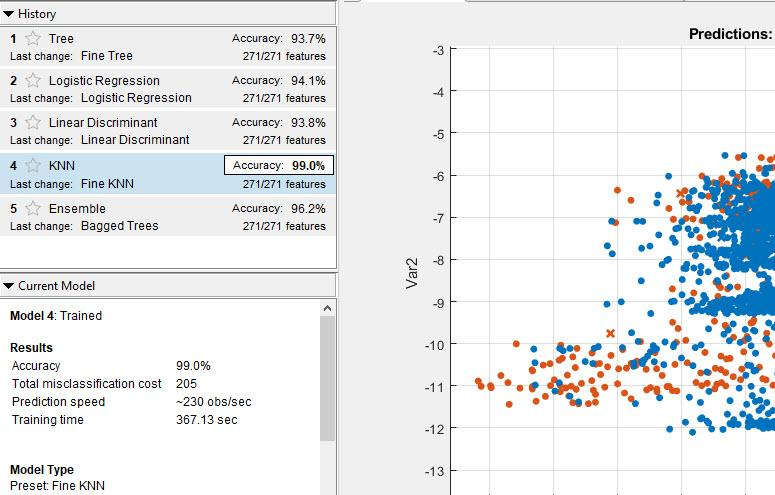

% After training your model on training_set (or the whole train_data),
% To evaluate accuracy on the unseen validation data:
% 1. Export your best model trained on wavelet features as "Compact" model
% 2. Modify the code below to calculate accuracy on "test_set"
%    (which may be the validation data, depending on how you prepared it)
% Shown below for KNN-model exported as "trainedModel"

predicted_wavelet = predict(trainedModel.ClassificationKNN, test_set);
conf_mat_wavelet = confusionmat(test_set.class, predicted_wavelet);
disp("Accuracy of the model based on automatically derived wavelet features:")
accuracy = (conf_mat_wavelet(1,1)+conf_mat_wavelet(2,2)) / size(test_set,1)

*Note: Expect accuracy of the model trained on the full set of 270+ wavelet features above 90% (we got 94% on held-out training data, but just 85% on validation).*